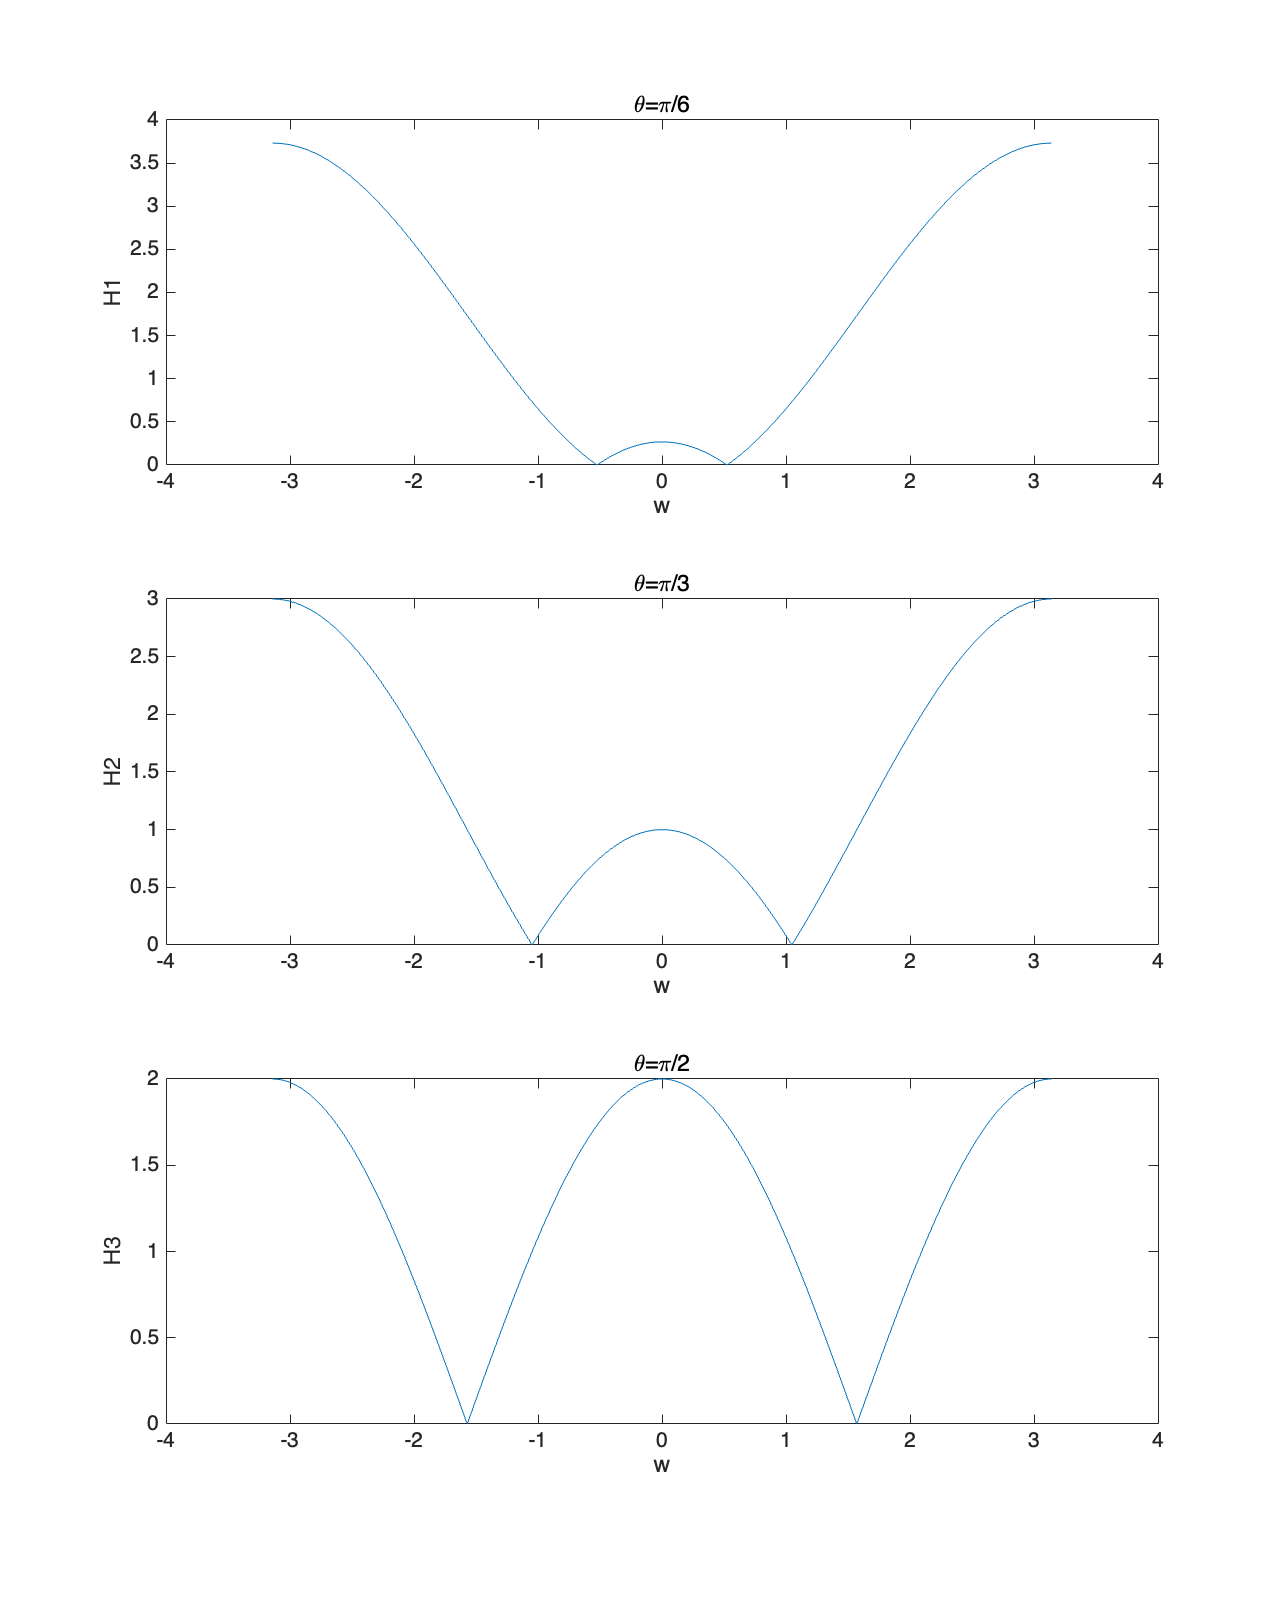

%7.3
w = linspace(-pi,pi,1000);
z = exp(-1j*w);
H1 = 1 - 2*cos(pi/6)*z.^(-1)+z.^(-2);
H2 = 1 - 2*cos(pi/3)*z.^(-1)+z.^(-2);
H3 = 1 - 2*cos(pi/2)*z.^(-1)+z.^(-2);
figure('Position', [100 100 800 1000]);
subplot(311),plot(w,abs(H1)),xlabel('w'),ylabel('H1'),title('\theta=\pi/6');
subplot(312),plot(w,abs(H2)),xlabel('w'),ylabel('H2'),title('\theta=\pi/3');
subplot(313),plot(w,abs(H3)),xlabel('w'),ylabel('H3'),title('\theta=\pi/2');

要求的差分方程写在平板上了

- **零点位置**：从传递函数可知，该滤波器的零点位于 z1=ejθ 和 z2=e−jθ。

- **频域特性**：频率响应是在单位圆上评估的 (z=ejω)。当频率*ω* 等于 θ(或 −θ) 时，传递函数的值变为零：H(ejθ)=1−2cos (θ)e−jθ+e−j2θ=0*H*(*e**j**θ*)=1−2cos(*θ*)*e*−*j**θ*+*e*−*j*2*θ*=0这意味着频率为 ω=±θ的信号分量会被完全滤除（增益为0）。

- **结论**：θ*θ***的值即为被该滤波器“剔除”或“阻断”的角频率。** 随着 θ 从 π/6增加到 π/2，滤波器的陷波位置（幅度为0的最低点）会沿着频率轴从低频向高频移动。

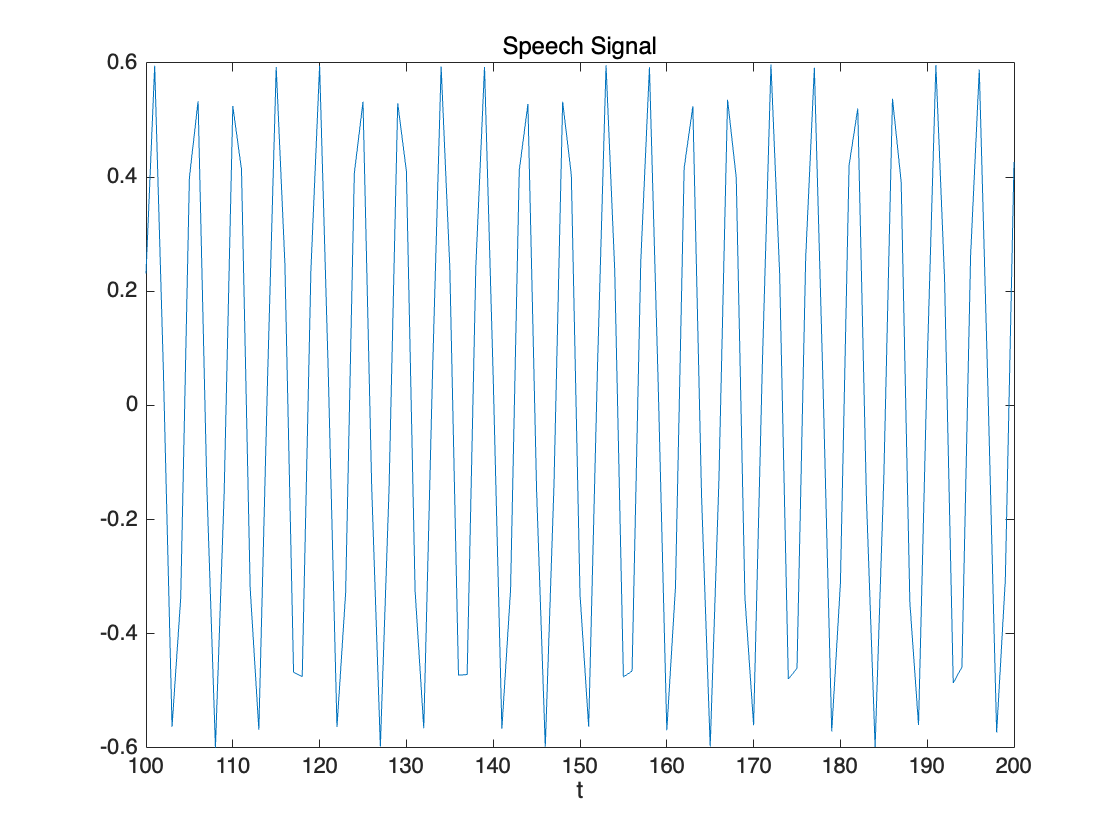

load nspeech1.mat;
sound(nspeech1);
figure;
plot(100:200,nspeech1(100:200)),xlabel('t'),title('Speech Signal');

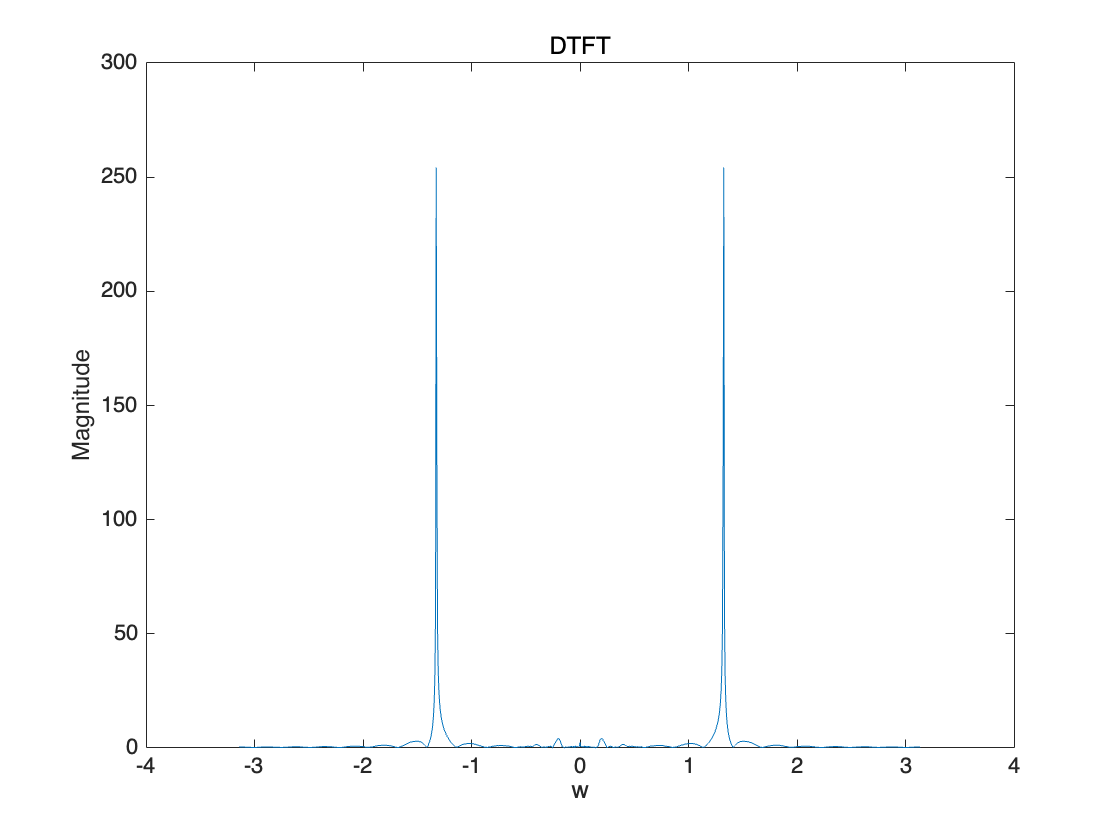

[X,w]=DTFT(nspeech1(100:1100),0);
figure;
plot(w,abs(X)),xlabel('w'),ylabel('Magnitude'),title('DTFT');

[Xmax,Imax] = maxk(abs(X),2);
theata = w(Imax)

theata =    -1.3254    1.3254


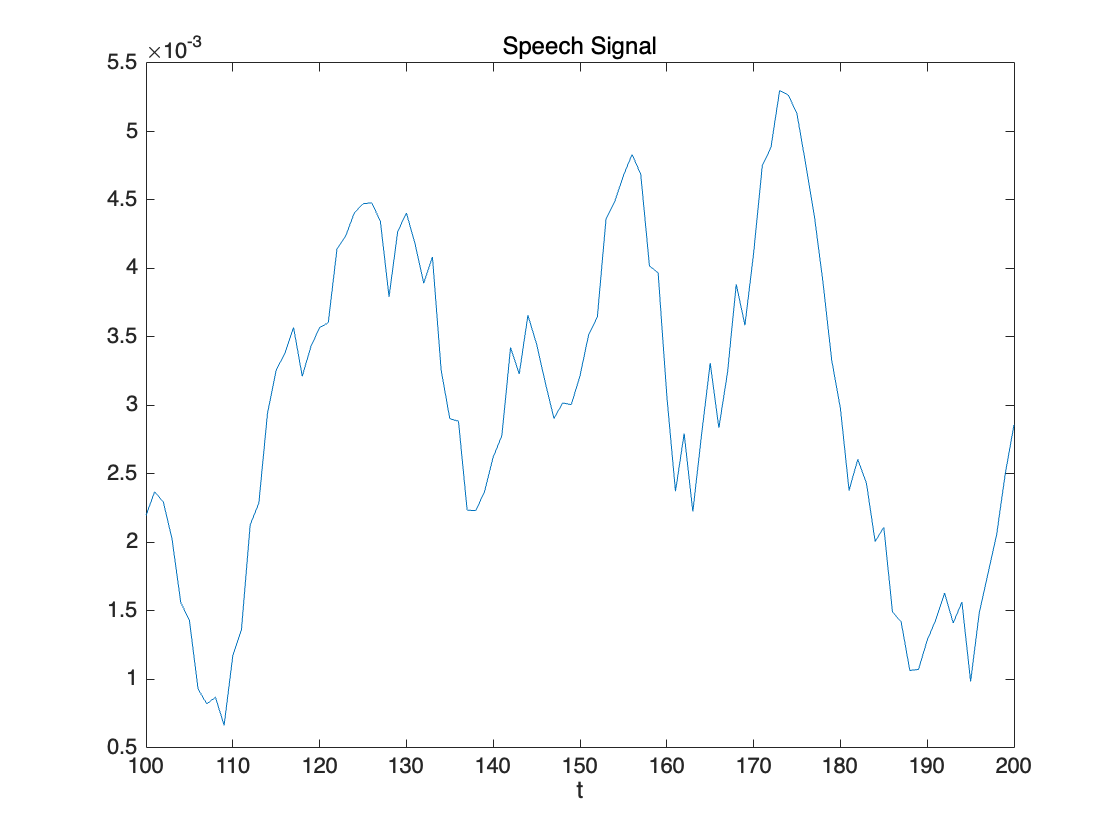

%滤波后音频
nspeech1c = FIRfilter(nspeech1);
sound(nspeech1c);
figure;
plot(100:200,nspeech1c(100:200)),xlabel('t'),title('Speech Signal');

[X,w]=DTFT(nspeech1(100:1100),0);
figure;
plot(w,abs(X)),xlabel('w'),ylabel('Magnitude'),title('DTFT');

频率部分变化：滤波过程专门移除了对应于 θ值的单一频率分量（正弦干扰）。在 ω=±θ处的 DTFT 幅度大幅下降。其余的频率成分（语音信号）基本未受影响并得以保留。

Bandstop滤波器（只针对ω=±θ处进行削减）

对音频质量的影响：人声更加清晰可见，一个高频的噪声被移除了。

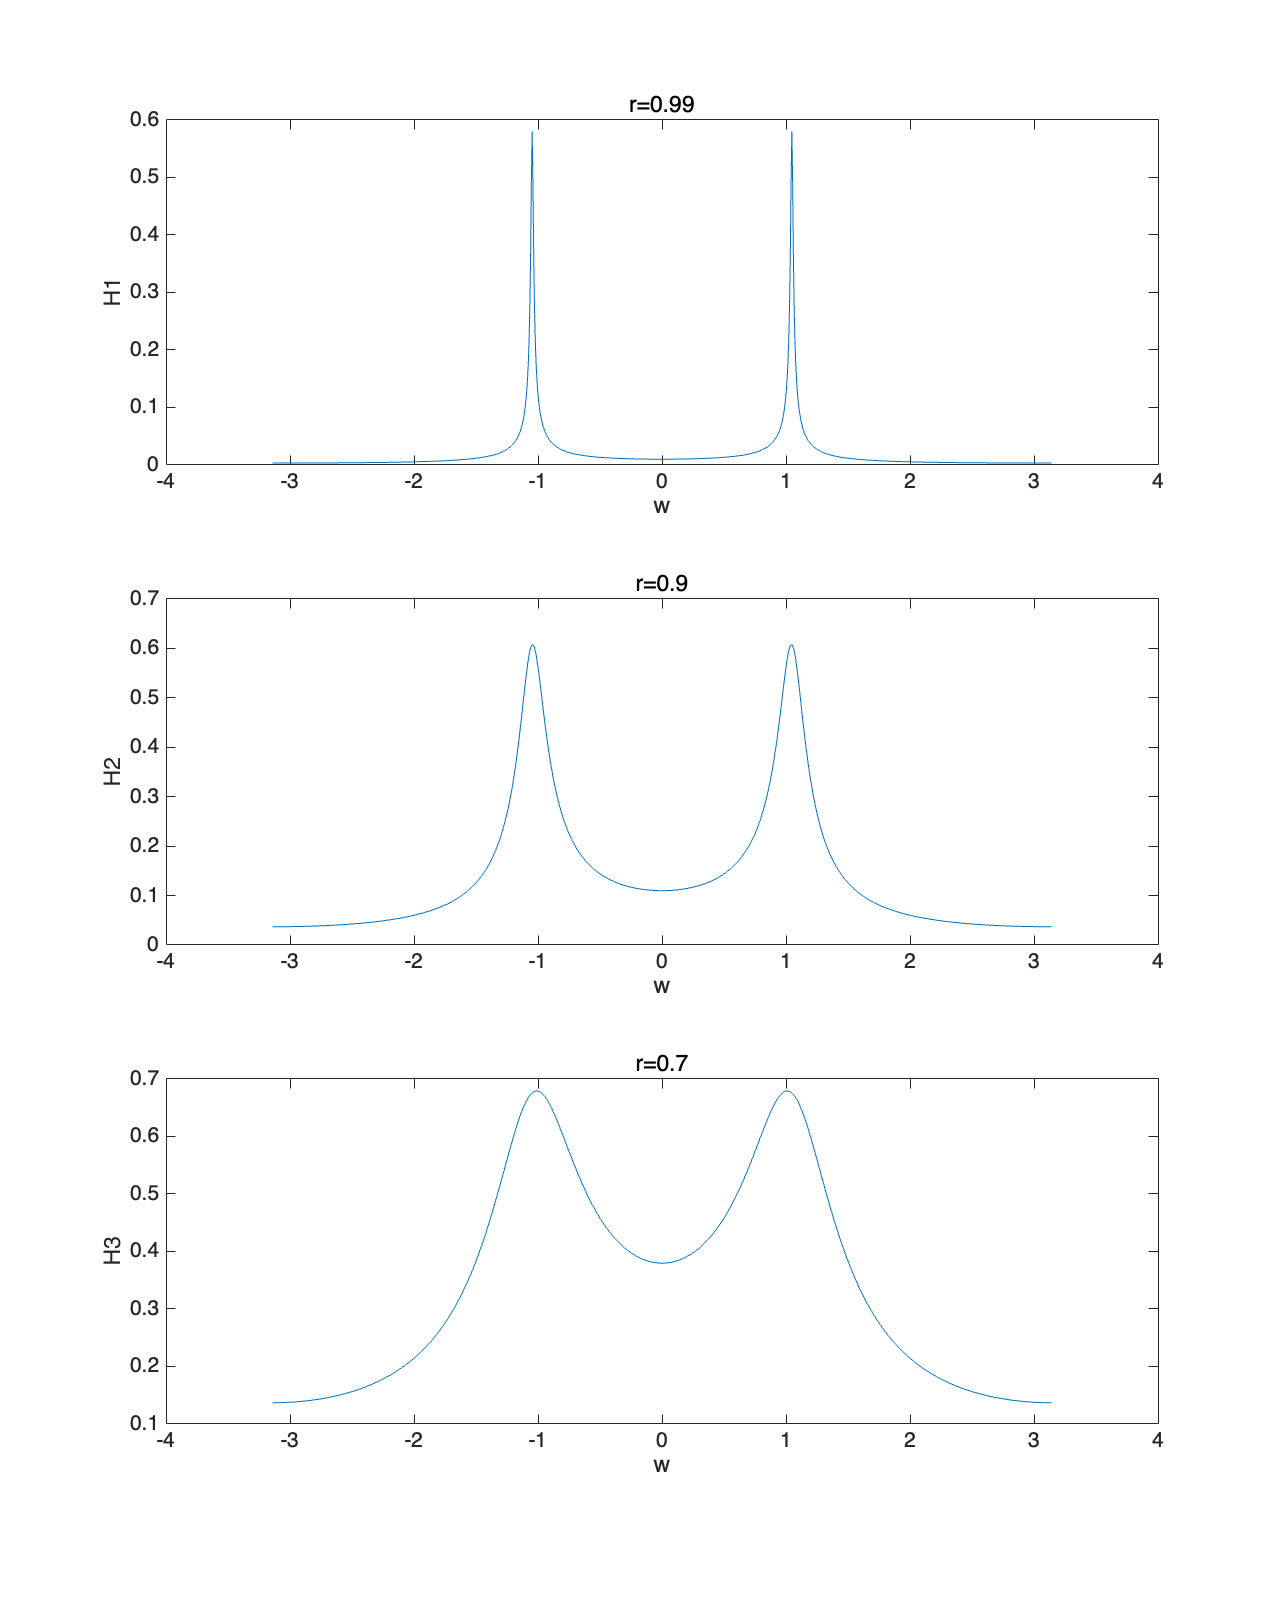

%7.4
w = linspace(-pi,pi,1000);
z = exp(-1j*w);
r = 0.99;
H1 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
r = 0.9;
H2 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
r = 0.7;
H3 = (1-r)./(1-2*r*cos(pi/3)*z.^(-1)+r^2*z.^(-2));
figure('Position', [100 100 800 1000]);
subplot(311),plot(w,abs(H1)),xlabel('w'),ylabel('H1'),title('r=0.99');
subplot(312),plot(w,abs(H2)),xlabel('w'),ylabel('H2'),title('r=0.9');
subplot(313),plot(w,abs(H3)),xlabel('w'),ylabel('H3'),title('r=0.7');

要求的差分方程写在平板上了

- r=0.99：峰值**极窄且尖锐**。

- r=0.9：峰值变宽，尖锐度下降。

- *r*=0.7：峰值变得**非常宽和平缓**

load pcm.mat;
sound(pcm);

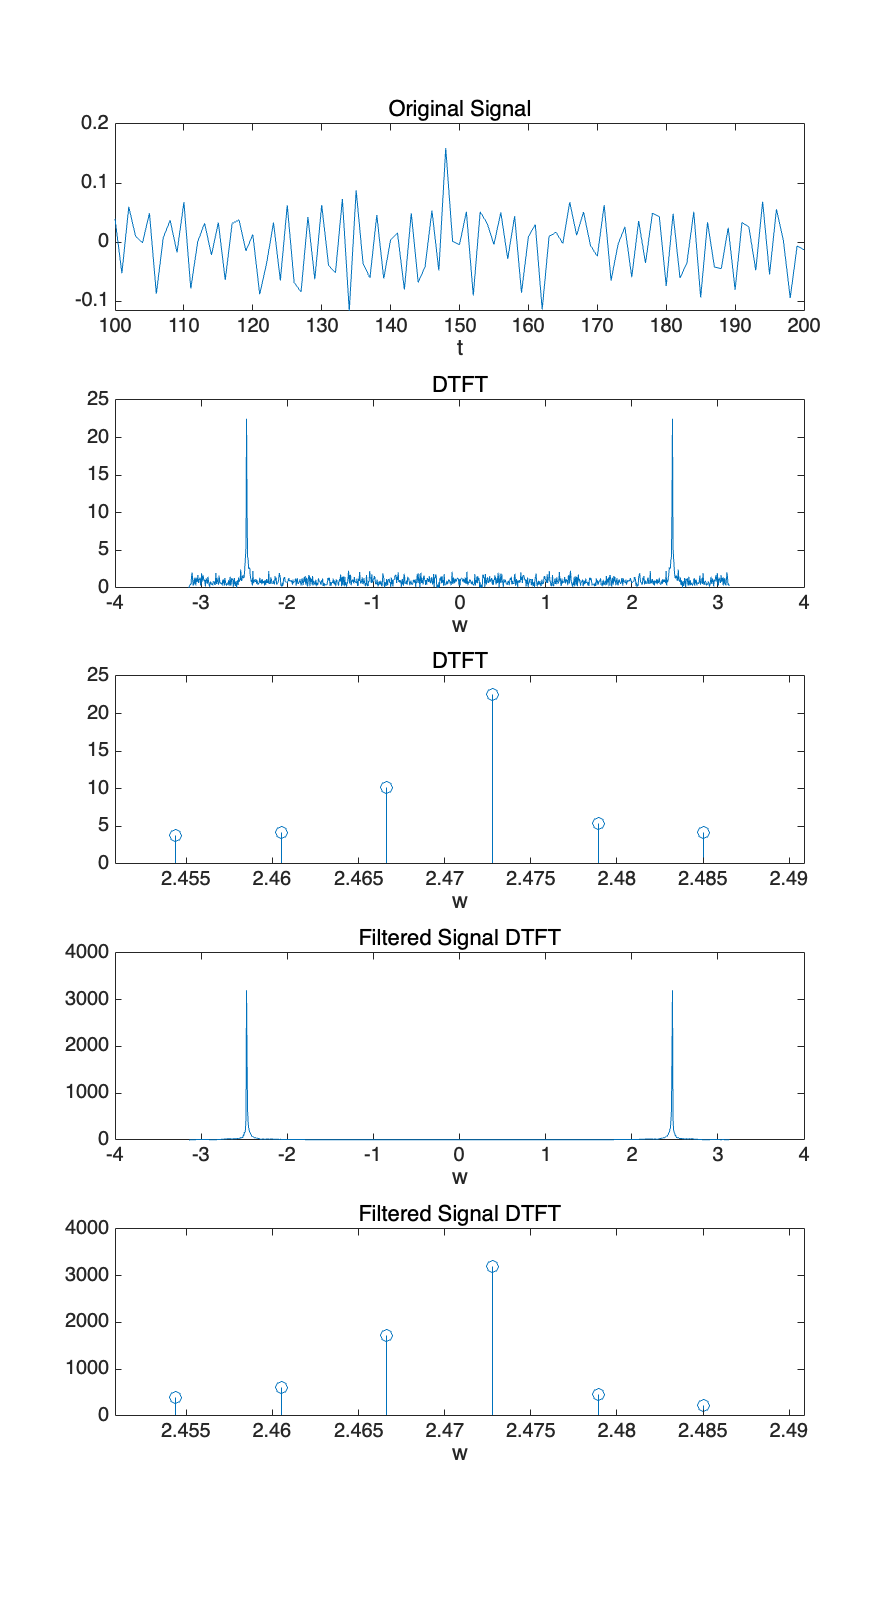

sound(IIRfilter(pcm));
figure('Position', [100 100 1000 1800]);
subplot(511),plot(100:200,pcm(100:200)),xlabel('t'),title('Original Signal');
[X,w] = DTFT(pcm(100:1100),0);
subplot(512),plot(w,abs(X)),xlabel('w'),title('DTFT');
%具体看一下中心频率附近的DTFT
subplot(513),stem(w,abs(X)),xlabel('w'),title('DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);
[X,w] = DTFT(IIRfilter(pcm(100:1100)),0);
subplot(514),plot(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT');
subplot(515),stem(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);

- **滤波前:** 声音听起来主要是巨大的“沙沙”声或静电噪音（白噪声），虽然能隐约听到后面有一个高音，但被噪声严重掩盖。

- **滤波后:** 刺耳的沙沙声完全消失了。现在只能听到一个清晰、纯净的高音（被调制的正弦波音调）。

- **当** r*r***增大（更接近 1）时:** 滤波器的通带变得**更窄 (Narrower)**。这意味着它能滤除更多的背景噪声，频率选择性更好，但对中心频率的准确性要求更高。

- **当** r**减小（远离 1）时:** 滤波器的通带变得**更宽 (Wider)**。这意味着会有更多的背景噪声通过滤波器，输出信号可能不如高 r*r* 值时那么纯净。

- **带宽与信号频谱的关系 (Signal Spectrum):**题目提示我们要考虑“期望信号的频谱”。这里的期望信号不是一个单纯的正弦波，而是一个**已调信号 (Modulated Signal)**。调制信号在频域上不是只有一根线，而是具有一定的**带宽 (Sidebands/边带)**。

- 如果 r极度接近 1（如 0.9999999），滤波器的带宽会变得**极窄**（近似于冲激函数）。

- 这样的滤波器会切除信号的边带，只保留载波频率。这不仅会丢失调制信息，还会严重扭曲信号的幅度包络。在本题中，听起来就像是高音一直持续，而不是一个间断的声音

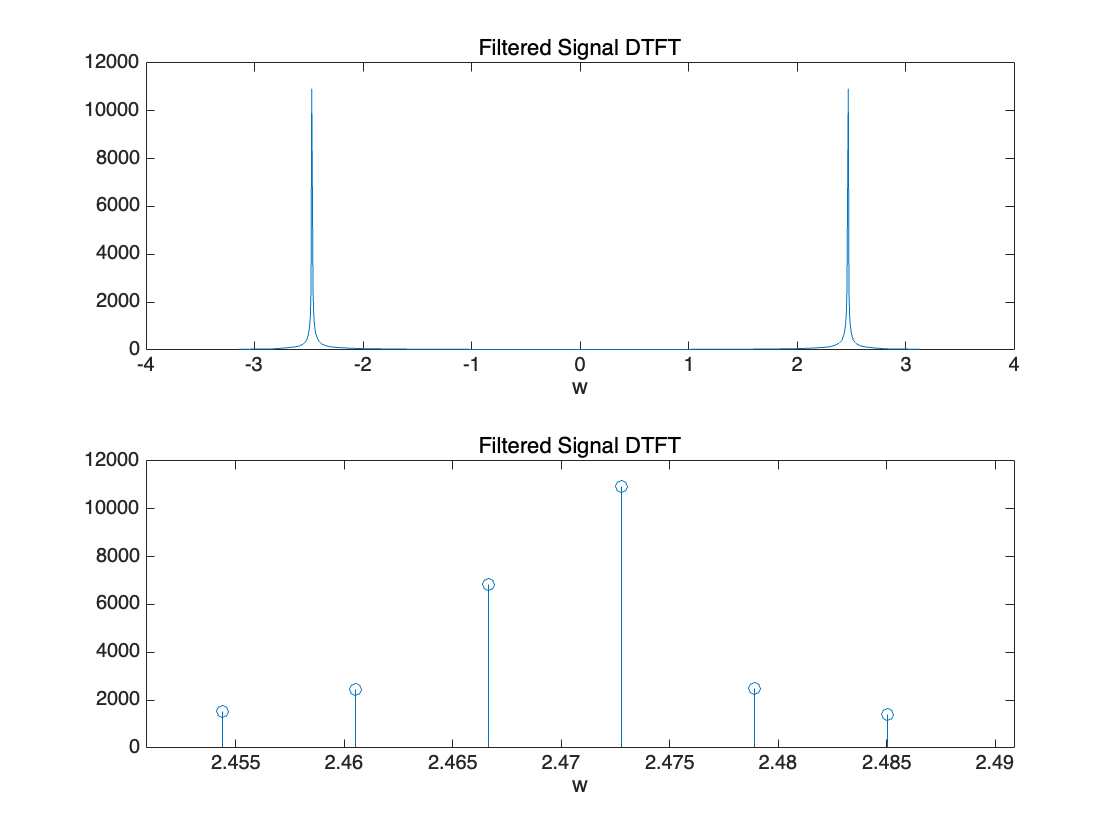

%试一下r=0.9999999，重写一个IIRfilter
figure;
[X,w] = DTFT(IIRfilter2(pcm(100:1100)),0);
sound(IIRfilter2(pcm));

subplot(211),plot(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT');
subplot(212),stem(w,abs(X)),xlabel('w'),title('Filtered Signal DTFT'),xlim([3146/4000*pi-0.02,3146/4000*pi+0.02]);

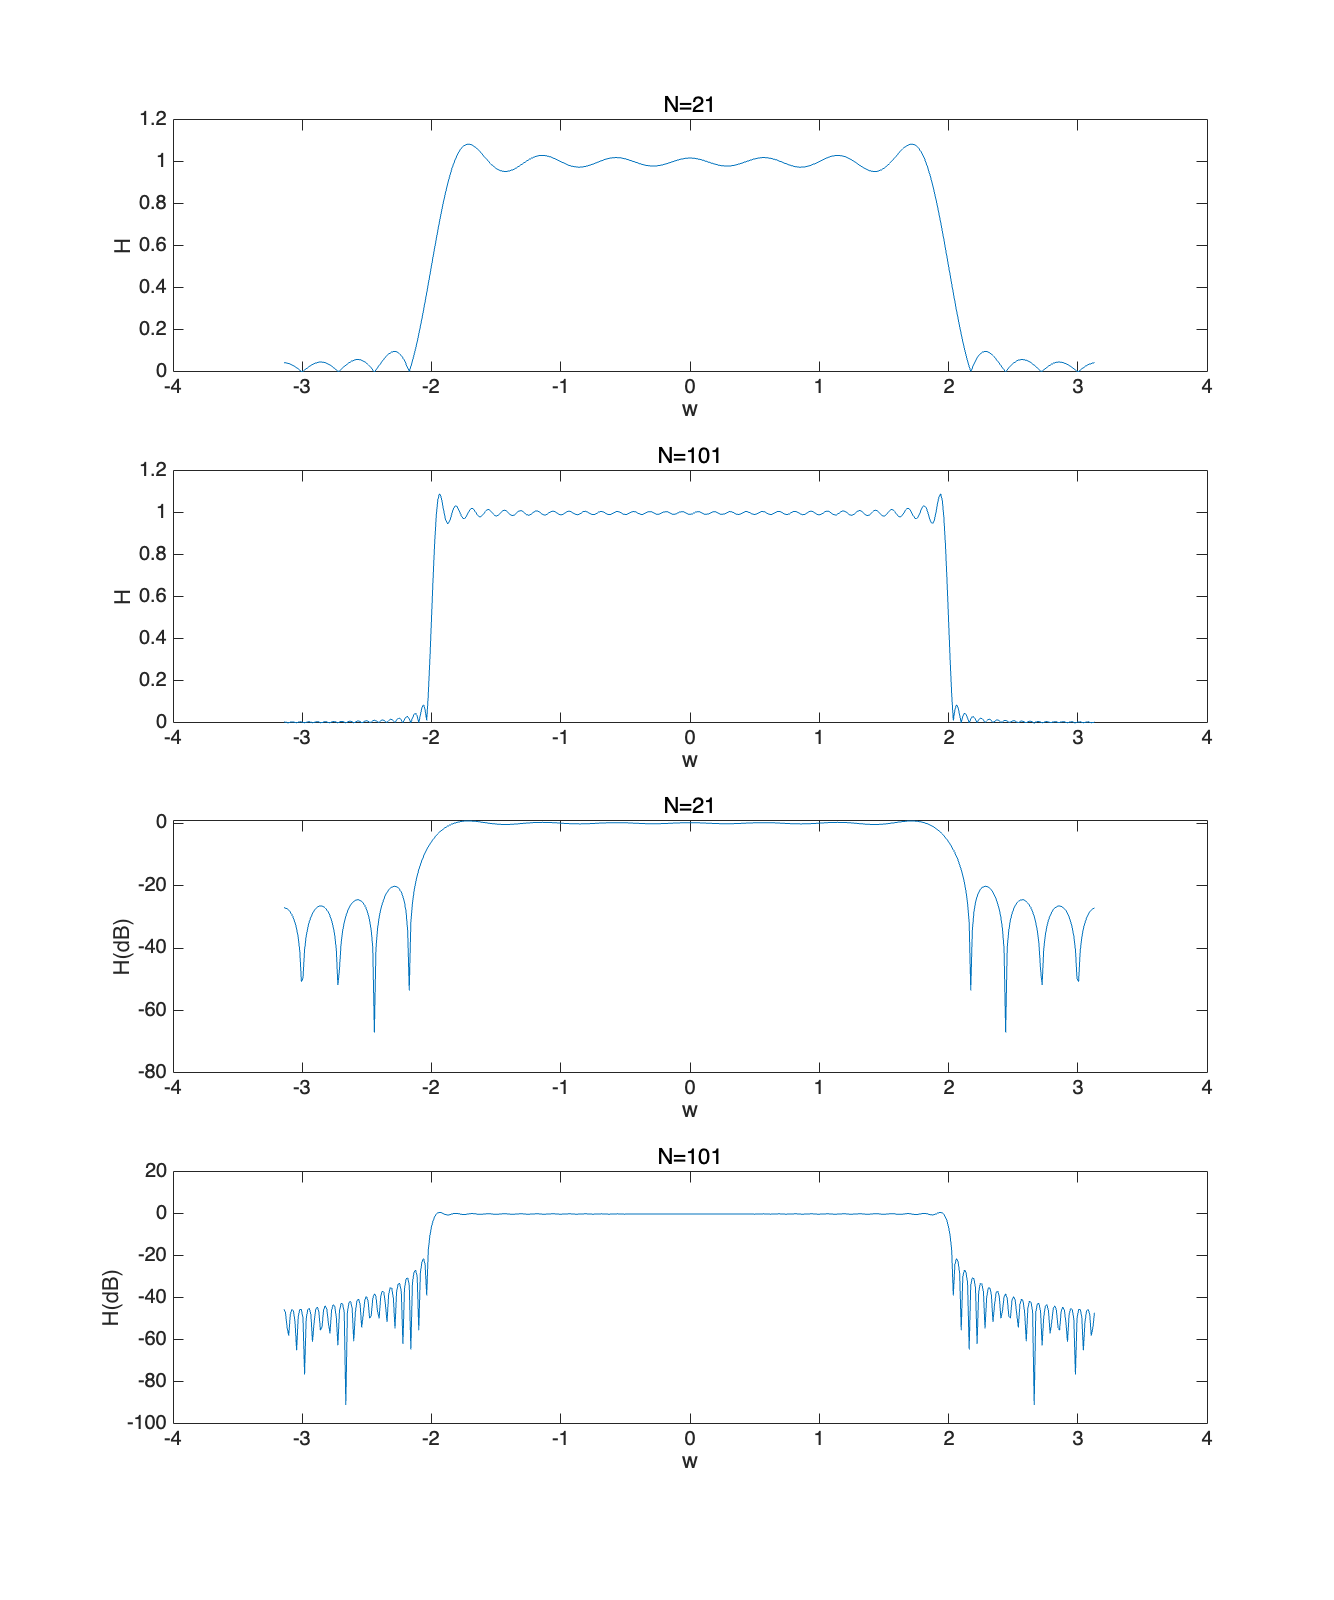

%7.6
clc,clear,close all;
load nspeech2.mat;
sound(nspeech2);
N1 = 21;
N2 = 101;
h1 = LPFtrunc(N1);
[X1, w1] = DTFT(h1,512);
h2 = LPFtrunc(N2);
[X2, w2] = DTFT(h2,512);
y1 = conv(nspeech2, h1); % N=21 的结果
y2 = conv(nspeech2, h2); % N=101 的结果
figure('Position', [100 100 1000 1200]);
subplot(411),plot(w1,abs(X1)),xlabel('w'),ylabel('H'),title('N=21');
subplot(412),plot(w2,abs(X2)),xlabel('w'),ylabel('H'),title('N=101');

subplot(413),plot(w1,20*log10(abs(X1))),xlabel('w'),ylabel('H(dB)'),title('N=21');
subplot(414),plot(w2,20*log10(abs(X2))),xlabel('w'),ylabel('H(dB)'),title('N=101');

对于第一第二张图，指出passband，transition band和stopband（口述）

增加N，会使得滤波后的stopband ripple的振荡频率变得更快，但是依然有吉布斯现象（旁瓣最高-13dB）的产生

- **原始信号**：背景中有很强的高频嘶嘶声（Noise）。

- **N = 21**：噪声有所减少，但可能仍能听到一些残留的高频噪声，因为过渡带太宽，截止不够干脆。

- **N = 101**：声音听起来比 N=21版本更清晰一些。

sound(y1)

sound(y2)

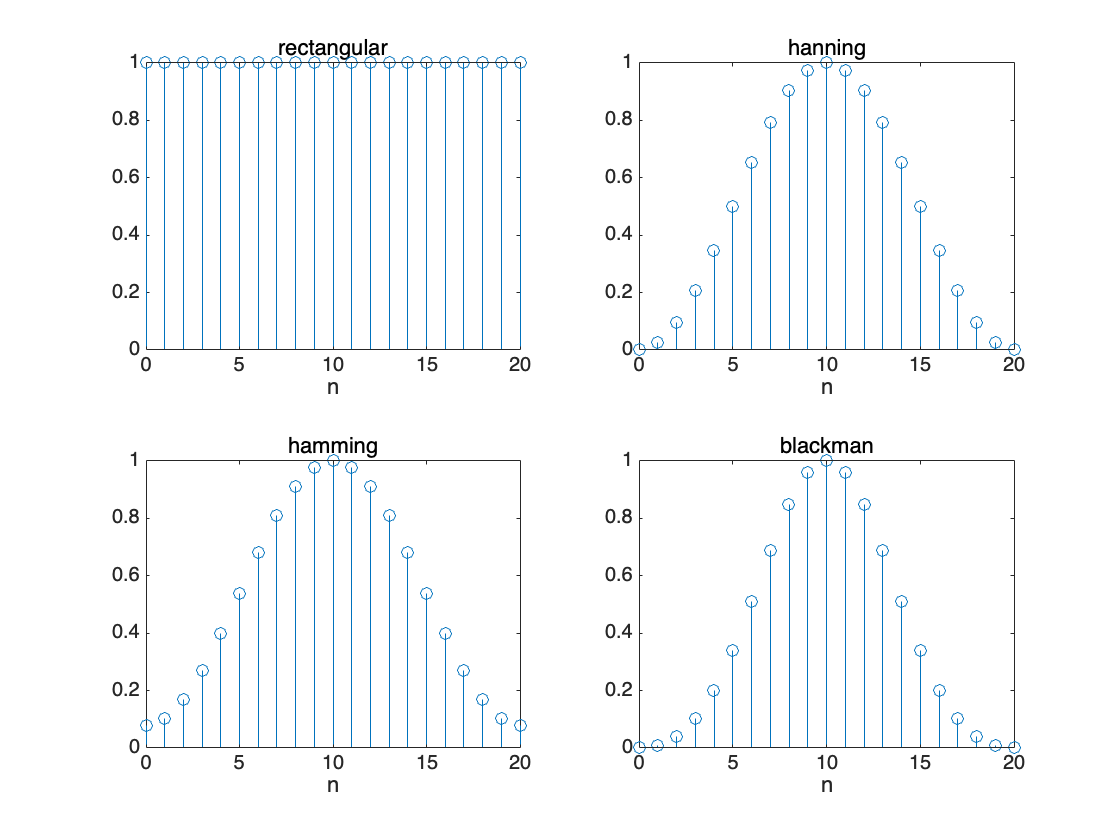

%7.7
%时域波形
clc,clear,close all;
N = 0:20;
rectangular = ones(21, 1);
hanning = hann(21);
hamm = hamming(21);
blackm = blackman(21);
figure;
subplot(221),stem(N,rectangular),xlabel('n'),title('rectangular');
subplot(222),stem(N,hanning),xlabel('n'),title('hanning');

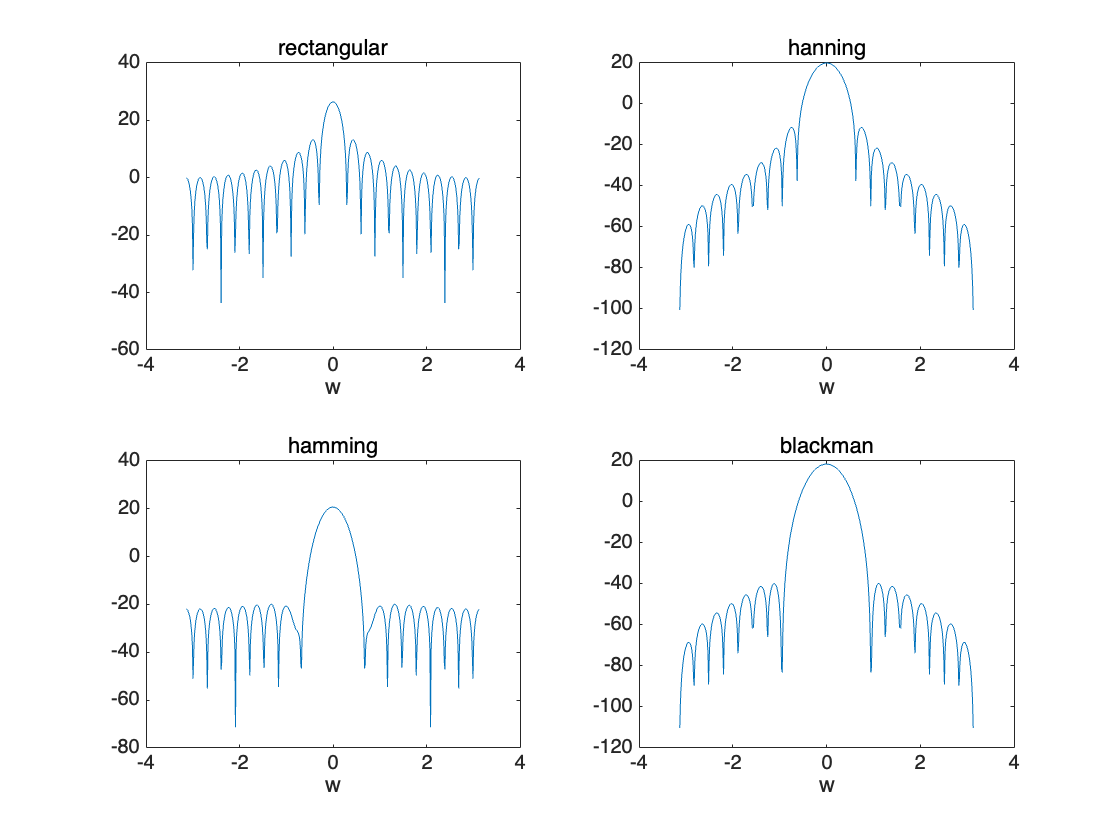

subplot(223),stem(N,hamm),xlabel('n'),title('hamming');
subplot(224),stem(N,blackm),xlabel('n'),title('blackman');
%DTFT
[X1, w1] = DTFT(rectangular, 512);
[X2, w2] = DTFT(hanning, 512);
[X3, w3] = DTFT(hamm, 512);
[X4, w4] = DTFT(blackm, 512);
figure;
subplot(221),plot(w1,20*log10(abs(X1))),xlabel('w'),title('rectangular');
subplot(222),plot(w2,20*log10(abs(X2))),xlabel('w'),title('hanning');

subplot(223),plot(w3,20*log10(abs(X3))),xlabel('w'),title('hamming');
subplot(224),plot(w4,20*log10(abs(X4))),xlabel('w'),title('blackman');H = ((2/pi) .* sinc((2/pi) .* (N - (0.5 * (length(N) - 1)))))';

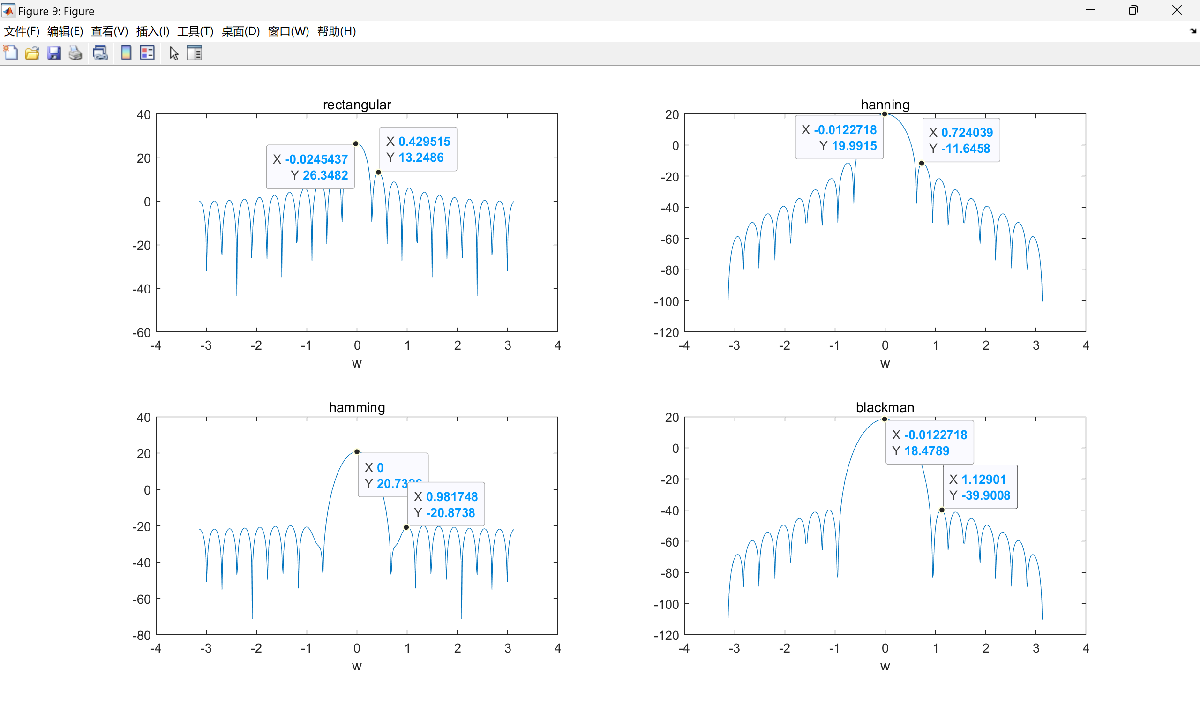

用Y坐标相减，可以看出基本符合理论值

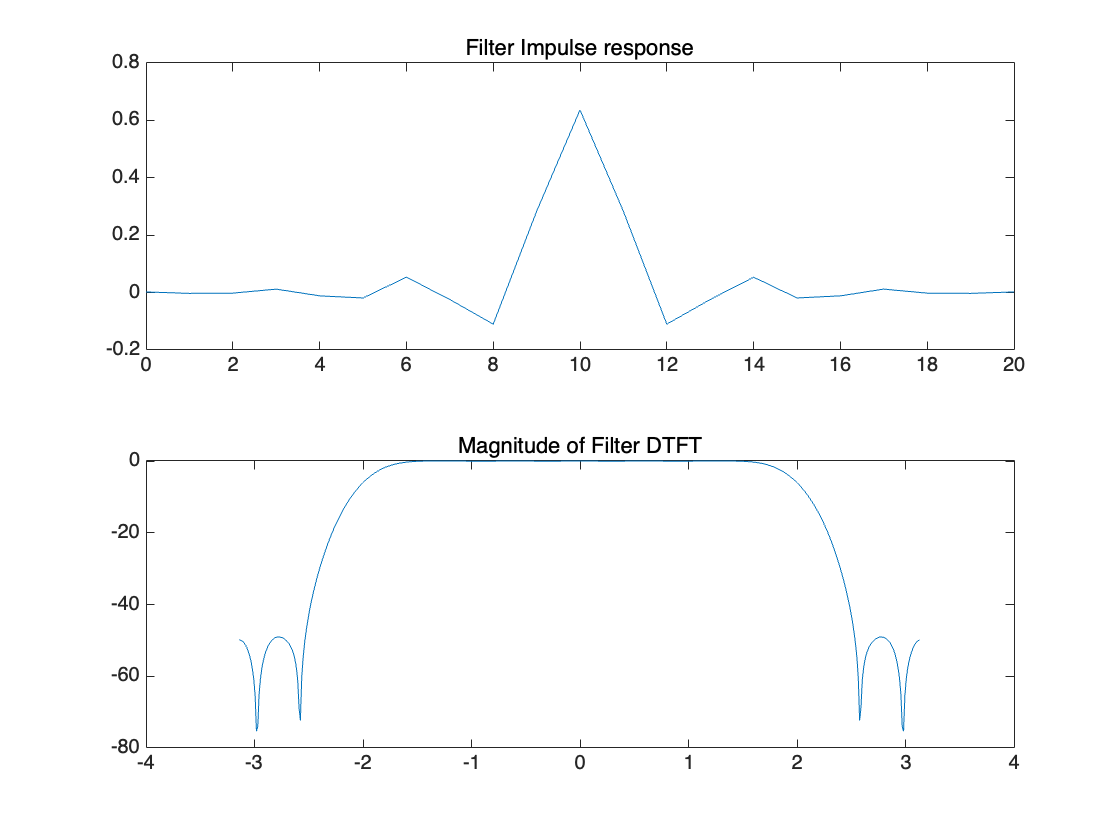

%Design：Hamming
w = H .* hamm;
[X, W] = DTFT(w, 512);
figure;

subplot(211),plot(N, w),title('Filter Impulse response');
subplot(212),plot(W, 20*log10(abs(X))),title('Magnitude of Filter DTFT');

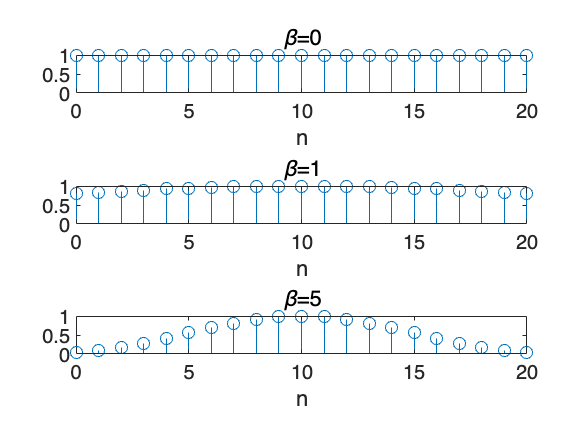

%7.8
clc,clear,close all;
load nspeech2.mat;
n = 0:20;
kaiserWindow1 = kaiser(21, 0);
kaiserWindow2 = kaiser(21, 1);
kaiserWindow3 = kaiser(21, 5);
figure;
subplot(311),stem(n,kaiserWindow1),xlabel('n'),title('\beta=0');
subplot(312),stem(n,kaiserWindow2),xlabel('n'),title('\beta=1');

subplot(313),stem(n,kaiserWindow3),xlabel('n'),title('\beta=5');

第二问需要计算过滤器的order，过程写在平板上了

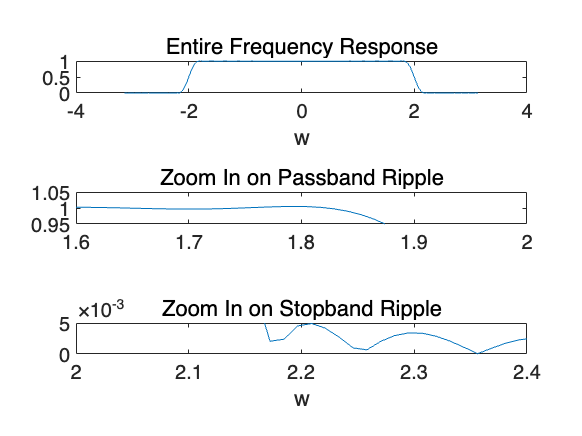

[X1, w1] = DTFT(kaiserWindow1, 512);
[X2, w2] = DTFT(kaiserWindow2, 512);
[X3, w3] = DTFT(kaiserWindow3, 512);
figure;
subplot(311),plot(w1,20*log10(abs(X1))),xlabel('w'),title('\beta=0');
subplot(312),plot(w2,20*log10(abs(X2))),xlabel('w'),title('\beta=1');
subplot(313),plot(w3,20*log10(abs(X3))),xlabel('w'),title('\beta=5');
omega_p = 1.8;
omega_c = 2.0;
omega_s = 2.2;
delta_p = 0.05;
delta_s = 0.005;
kaiserBeta = 4.0909;
filterOrder = 51;
kaiserWindow = kaiser(filterOrder, kaiserBeta);
filterImpulseResponse = LPFtrunc(filterOrder);
filteredFilter = filterImpulseResponse .* kaiserWindow';
[X, w] = DTFT(filteredFilter, 512);
subplot(311),plot(w, abs(X)),title('Entire Frequency Response'),xlabel('w');
subplot(312),plot(w, abs(X)),title('Zoom In on Passband Ripple'),axis([omega_p-0.2, omega_p+0.2, 1-delta_p, 1+delta_p]);
subplot(313),plot(w, abs(X)),title('Zoom In on Stopband Ripple'),xlabel('w'),axis([omega_s-0.2, omega_s+0.2, 0, delta_s]);

- **纹波直接看stopband2.2后面的最高峰即可（passband和stopband基本一致）**

- **设计要求:**

- 通带最大允许纹波 δp=0.05*δ**p*=0.05

- 阻带最大允许纹波 δs=0.005

- **判断:**

- 测量的通带纹波 0.0035<0.05 (满足)

- 测量的阻带纹波 0.0035<0.005 (满足)

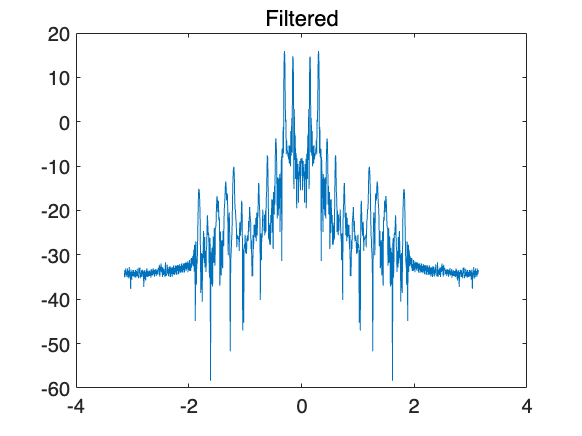

filteredSpeech = conv(filteredFilter, nspeech2);
[filteredDTFT, filteredOmega] = DTFT(filteredSpeech(20001:20400), 1024);
figure;
plot(filteredOmega, 20*log10(abs(filteredDTFT))),title('Filtered');

sound(nspeech2, 8000);
pause(length(nspeech2)/8000);%等放完了再放第二段
sound(filteredSpeech, 8000);

噪声更小了

function output = FIRfilter(x)
    [X,w] = DTFT(x,0);
    [Xmax,Imax] = max(abs(X));
    theta = w(Imax);
    h = [1, -2*cos(theta), 1];
    output = conv(x,h);
end

function y = IIRfilter(x)
    theta = (3146/8000)*2*pi;
    r = 0.995;
    N = length(x);
    y = zeros(1,N);
    y(1) = x(1);
    y(2) = x(2) + 2*r*cos(theta);
    for i = 3:N
        y(i) = x(i) + 2*r*cos(theta).*y(i-1) - (r^2).*y(i-2);
    end
end

function y = IIRfilter2(x)
    theta = (3146/8000)*2*pi;
    r = 0.99999999;
    N = length(x);
    y = zeros(1,N);
    y(1) = x(1);
    y(2) = x(2) + 2*r*cos(theta);
    for i = 3:N
        y(i) = x(i) + 2*r*cos(theta).*y(i-1) - (r^2).*y(i-2);
    end
end

function h = LPFtrunc(N)
    for i = 1:N
        h(i) = 2/pi*sinc(2/pi*(i-1-(N-1)/2));
    end
end
